# VTT - Value of traffic information

## Input

clear global
clc
% read input data from the excel file, e.g., line, travel/waiting time, etc
[line, travel_time, alt_travel_time, waiting_time, avg_delay, delay_prob, OD_pax] = read_input('./1_scenario/data.xlsx');

## VTT for a commuter line

### > Estimation per trip (without using passenger OD)

% assess the value of train traffic information in terms of accessibility
delta_R_time = assess_vtt("time-trip", line, travel_time, alt_travel_time, waiting_time, avg_delay, delay_prob, []);
% assess the value of train traffic information in terms of social costs
delta_R_cost = assess_vtt("cost-trip", line, travel_time, alt_travel_time, waiting_time, avg_delay, delay_prob, []);
% Non-weighted average
agg_R_time_avg = aggregate_vtt("avg", delta_R_time, [])

agg_R_time_avg = 0.5855

agg_R_cost_avg = aggregate_vtt("avg", delta_R_cost, [])

agg_R_cost_avg = 1.4226

agg_R_cost_avg/agg_R_time_avg

### > Estimation over a working day (using passenger OD)

% Weighted average (with nb of pax)
agg_R_time_pax = aggregate_vtt("pax_weight", delta_R_time, OD_pax)

agg_R_time_pax = 0.5224

agg_R_cost_pax = aggregate_vtt("pax_weight", delta_R_cost, OD_pax)

agg_R_cost_pax = 1.1024

agg_R_cost_pax/agg_R_time_pax
% similarly including the daily passengers
delta_R_time_day = assess_vtt("time-day", line, travel_time, alt_travel_time, waiting_time, avg_delay, delay_prob, OD_pax);
delta_R_cost_day = assess_vtt("cost-day", line, travel_time, alt_travel_time, waiting_time, avg_delay, delay_prob, OD_pax);

### > Plots of the estimation results

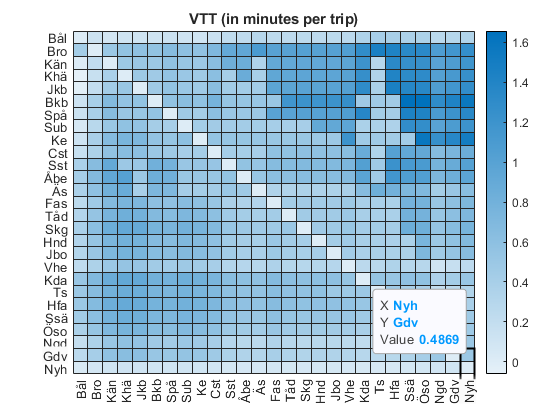

% Heat map X->Y and Z is the VTT in terms of travel time
plot_figure("time-trip",line,delta_R_time)

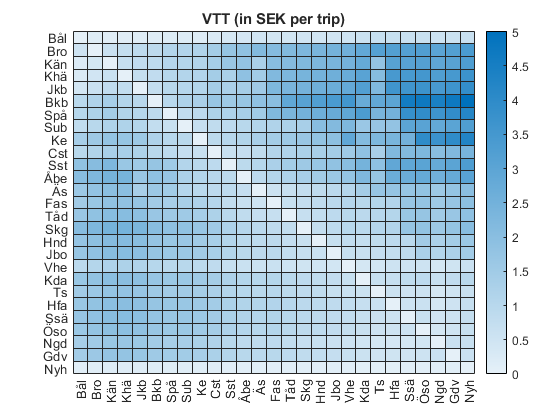

% In terms of costs/trip
plot_figure("cost-trip",line,delta_R_cost)

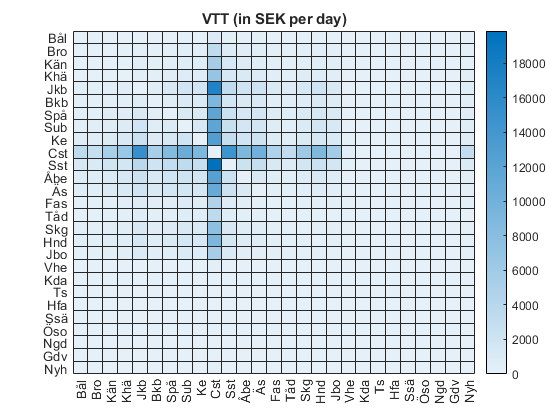

% In terms of costs per day
plot_figure("cost-day",line,delta_R_cost_day)

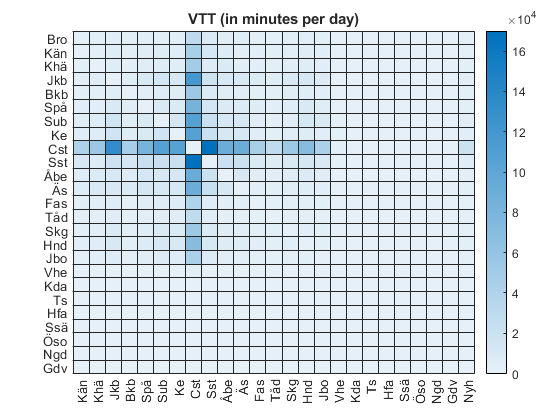

% In terms of time per day
plot_figure("time-day",line,delta_R_time_day)

## Sensitivity analyses

### >  VTT calculation - delays (length and probability)

delay_prob_param = 0.001:.2:2;
delay_param = 0.001:.2:2;
agg_R_time_avg_prob = zeros(size(delay_prob_param,2),size(delay_param,2));
agg_R_cost_avg_prob = zeros(size(delay_prob_param,2),size(delay_param,2));
agg_R_time_pax_prob = zeros(size(delay_prob_param,2),size(delay_param,2));
agg_R_cost_pax_prob = zeros(size(delay_prob_param,2),size(delay_param,2));
for p=1:size(delay_param,2)
    for i=1:size(delay_prob_param,2)
        % assess the value of train traffic information in terms of accessibility
        delta_R_time = assess_vtt("time-trip", line, travel_time, alt_travel_time, waiting_time, delay_param(p)*avg_delay, delay_prob_param(i)*delay_prob, []);
        % assess the value of train traffic information in terms of social costs
        delta_R_cost = assess_vtt("cost-trip", line, travel_time, alt_travel_time, waiting_time, delay_param(p)*avg_delay, delay_prob_param(i)*delay_prob, []);
        % Non-weighted average
        agg_R_time_avg_prob(i,p) = aggregate_vtt("avg", delta_R_time, []);
        agg_R_cost_avg_prob(i,p) = aggregate_vtt("avg", delta_R_cost, []);
        % Weighted average (with nb of pax)
        agg_R_time_pax_prob(i,p) = aggregate_vtt("pax_weight", delta_R_time, OD_pax);
        agg_R_cost_pax_prob(i,p) = aggregate_vtt("pax_weight", delta_R_cost, OD_pax);
    end
end

### > Plots

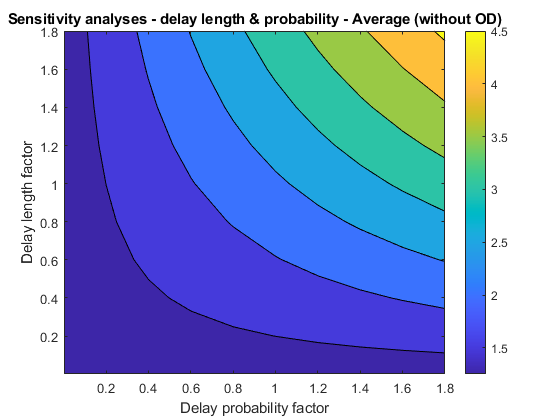

% Plot the results as contours
figure;
contourf(delay_prob_param, delay_param, agg_R_cost_avg_prob./agg_R_time_avg_prob);
colorbar;
xlabel('Delay probability factor');
ylabel('Delay length factor');
title('Sensitivity analyses - delay length & probability - Average (without OD)');

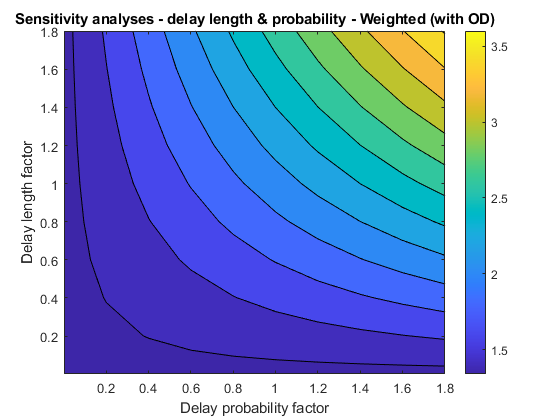

% Plot the results as contours
figure;
contourf(delay_prob_param, delay_param, agg_R_cost_pax_prob./agg_R_time_pax_prob);
colorbar;
xlabel('Delay probability factor');
ylabel('Delay length factor');
title('Sensitivity analyses - delay length & probability - Weighted (with OD)');